clear all;
clc;

T = 1;
N = 30;
fs = 5120;  %4096;
Ts = 1/fs;

t = T*fs +1;

Tpp = 10;
Tsp = 10;

X_tonal = sin(2*pi*500*(0:Ts:T));
X_broad = rand(t,1);

% load('C:\Users\rnerd\Desktop\Codes\Matlab\ANC\Loaded files\Lathe.mat')
% X_lathe = downsample(Lathe.VarName2, 10);

% X_chaotic = 2*sin(2*pi*500*(0:Ts:T)/1000);
% for i=3:T*fs +1
% 
%     X_chaotic(i) = X_chaotic(i-2) + 0.08*X_chaotic(i-2)^2 - 0.04*X_chaotic(i-2)^3;
% end

set(groot, 'defaultFigureUnits', 'centimeters', 'defaultFigurePosition', [0 0 50 8]);

PP = transfer_func([1,-.3,0.2],[1,0,0,0,0,0,0,0],0,Ts,Tpp);
SP = transfer_func([1, 1.5, -1],[1,0,0,0,0],0,Ts,Tpp);

PP = PP/max(PP);
SP = SP/max(SP);

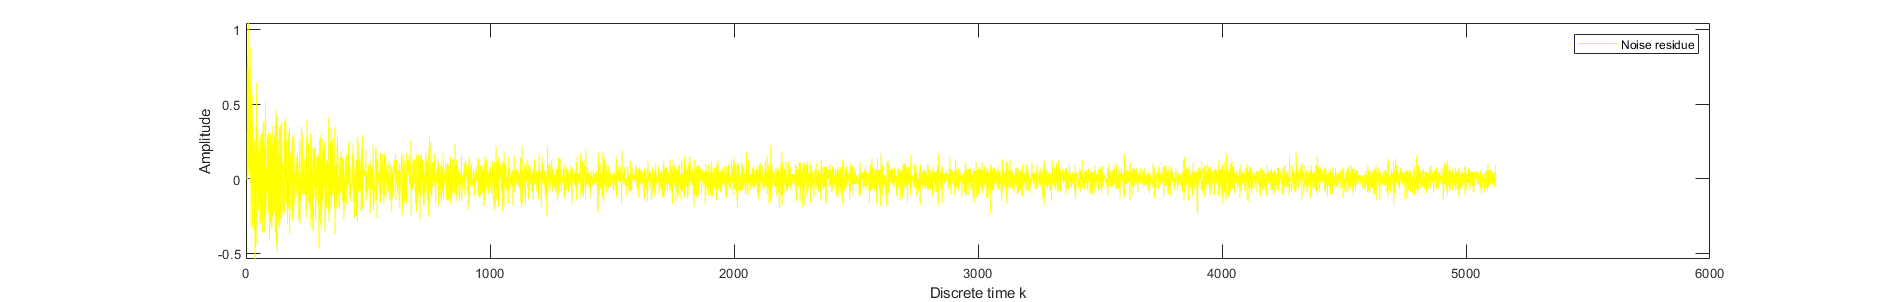

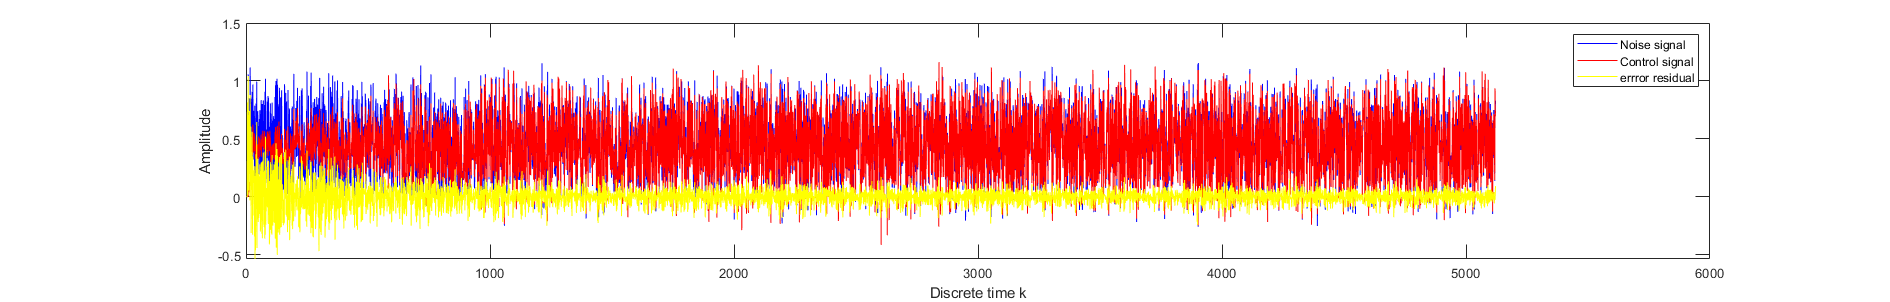

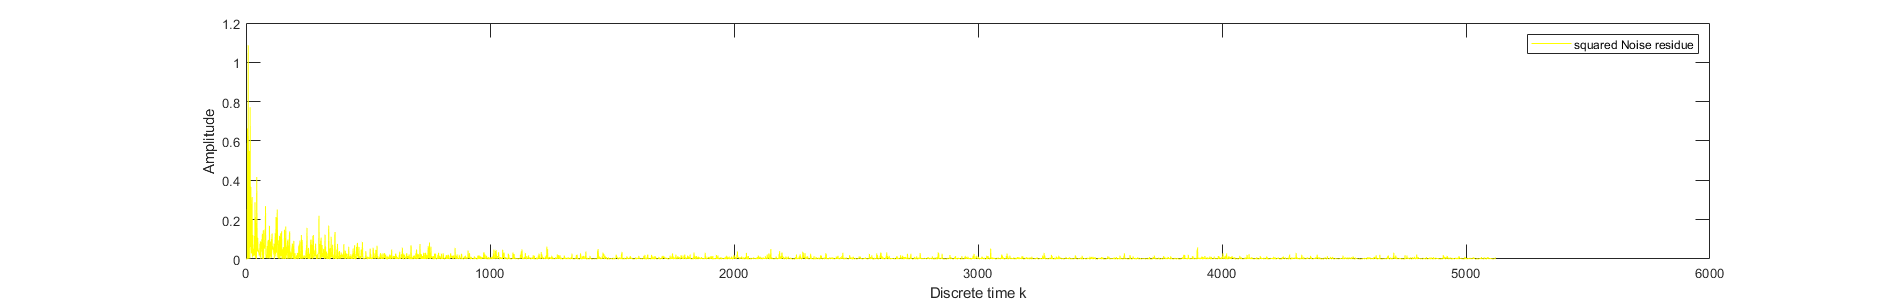

Vseries_broad = Vseries(X_broad, PP, SP,N, 10^-2, t);
ploting(Vseries_broad);

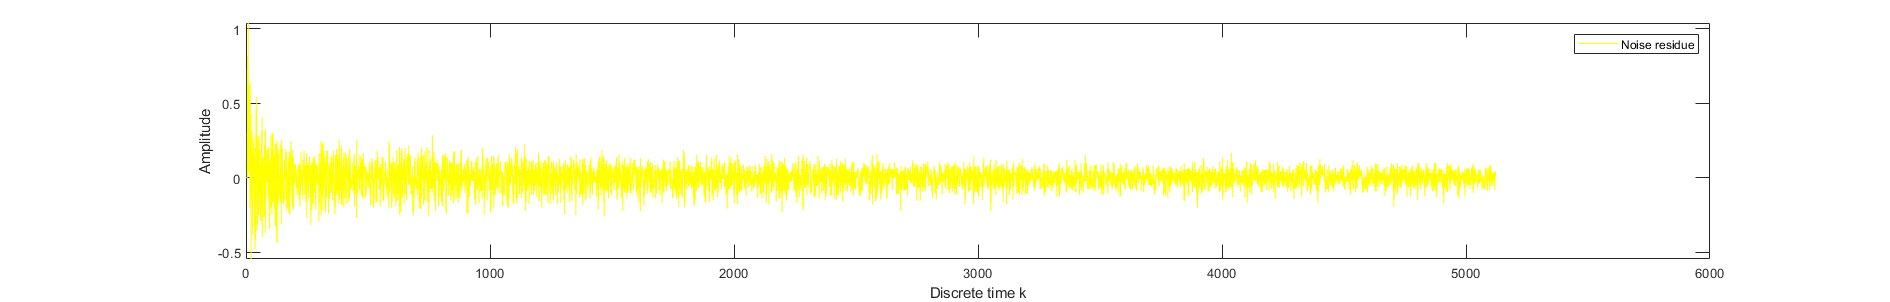

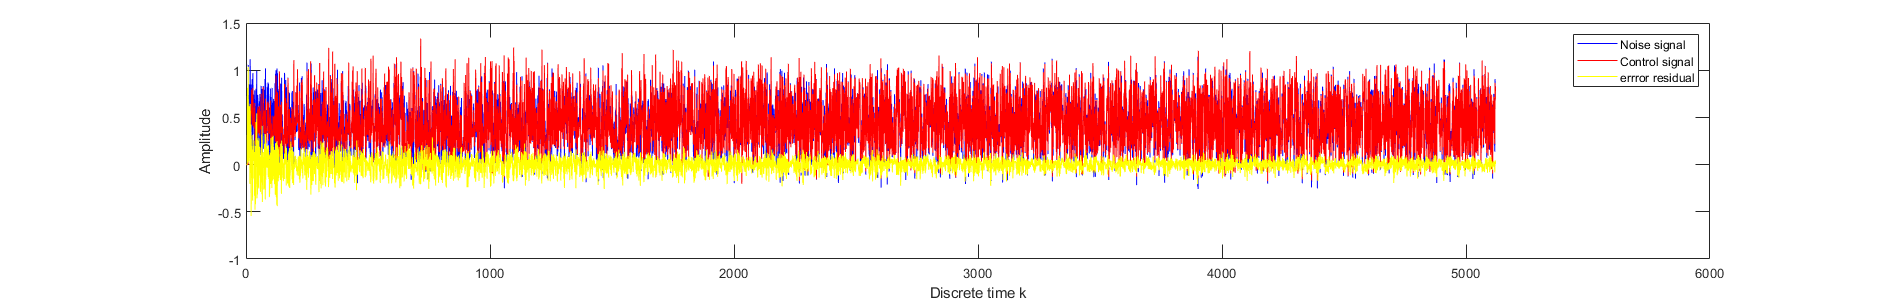

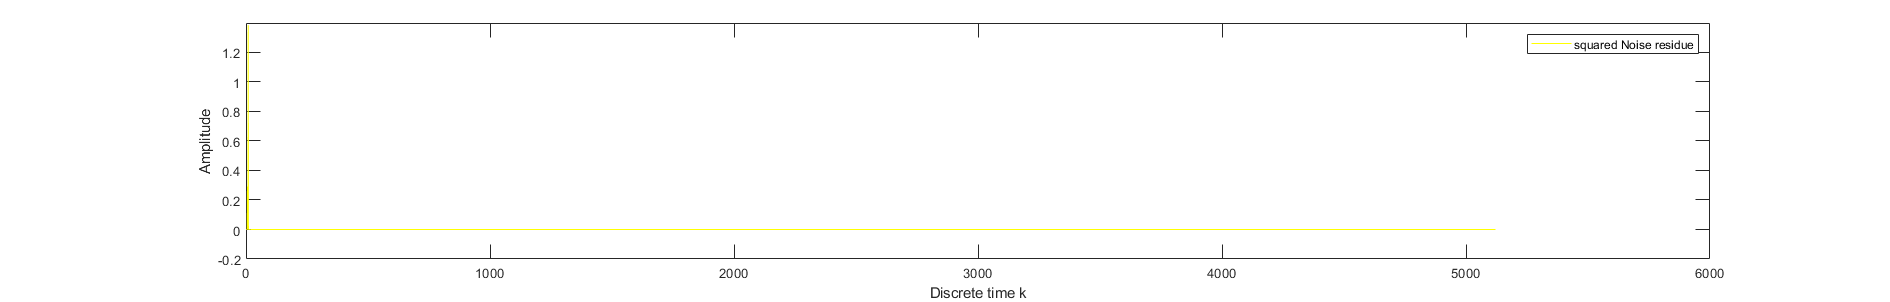

hamerstein_broad = Hamerstein(X_broad, PP, SP, N,6, 10^-2,t);
ploting(hamerstein_broad)

cheby_broad = chebyshev(X_broad, PP, SP, N, 6,10^-2.7, t)

cheby_broad =          0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
    0.8147    0.8147    0.6638
    0.6614    0.6614    0.4374
    0.0182    0.0182    0.0003
    1.0564    1.0492    1.1008
    0.3837    0.3656    0.1337


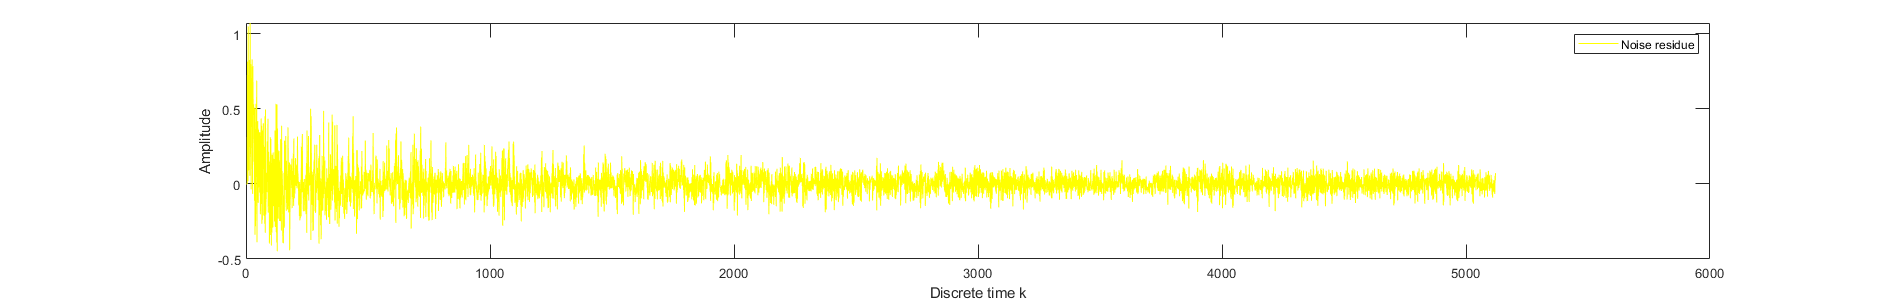

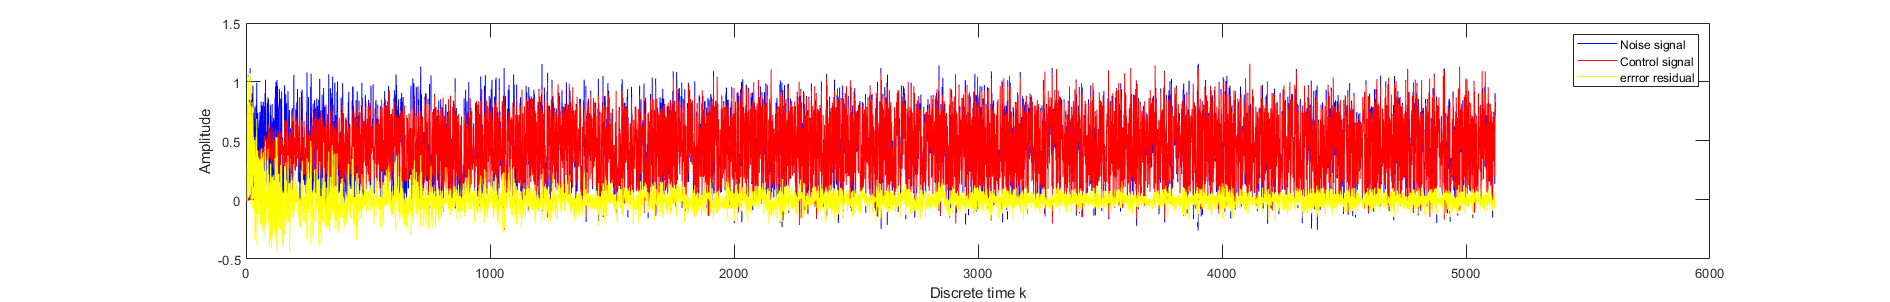

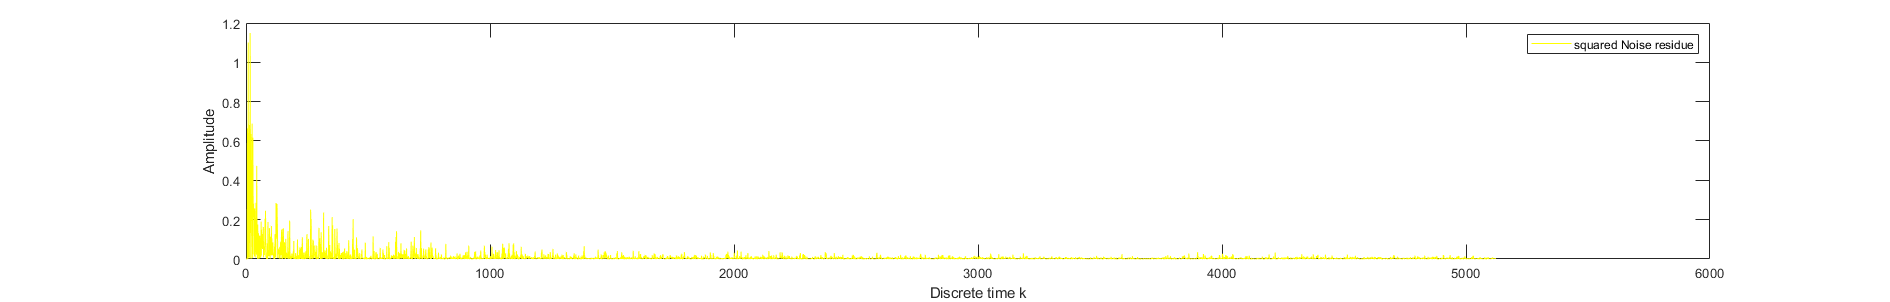

ploting(cheby_broad);

Fourier_broad = Fourier(X_broad, PP, SP, N, 10^-2,t)

Execution of script Fourier as a function is not supported:
C:\Users\rnerd\Desktop\Codes\Matlab\ANC\Fourier.m

ploting(Fourier_broad);